Αφού τρέξετε τον παρακάτω κώδικα δοκιμάστε τα παρακάτω:

- Αλλάξτε την συνάρτηση t = x+noise σε κάποια ποιο περίπλοκη ή συνδιασμό συναρτήσεων π.χ. t = cos(x) + x^2 +noise

- Δοκιμάστε διαφορετικούς αριθμούς νευρώνων και σιγά σιγά αυξήστε και τον αριθμό στρώσεων(layers)

- Στο nntraintool δοκιμάστε τα διάφορα plots που έχει στο pop-up window.

x = 1:10;
noise = rand(1,10)

noise =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649


t = x + noise;

t

t =     1.8147    2.9058    3.1270    4.9134    5.6324    6.0975    7.2785    8.5469    9.9575   10.9649


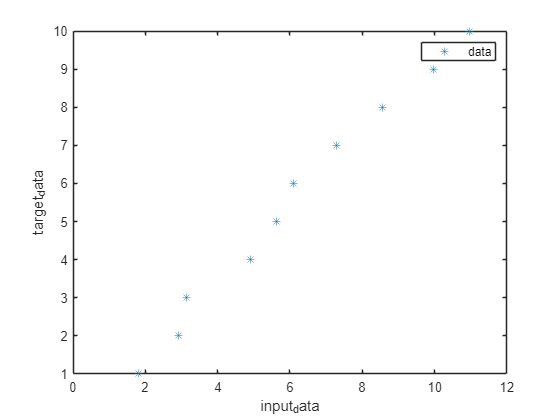

figure
plot(t,x, '*')
legend('data')
xlabel('input_data')
ylabel('target_data')

net = fitnet(10); 

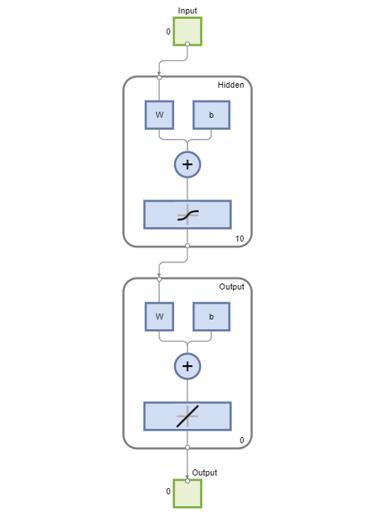

view(net)

net = configure(net, x, t)

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 31
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

view(net)

[net, tr] = train(net, x, t);

preds = net(x) 

preds =     1.2543    2.8143    3.2435    6.7442    5.3500    5.2904    7.3317    8.5693    9.4733   10.3517


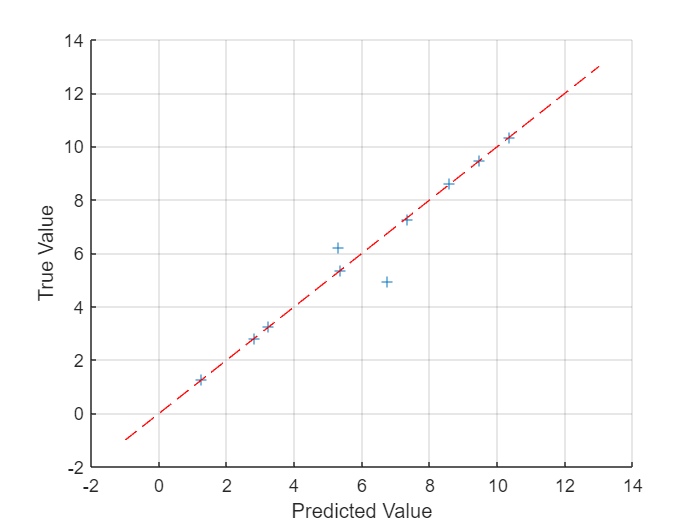

figure
scatter(preds,t,'+')
xlabel("Predicted Value")
ylabel("True Value")
grid on
hold on
hold on
plot([-1 13], [-1 13],'r--')